Ejemplo de diseño de filtro digital

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

**Cálculo de la función de transferencia**

% Función de transferencia - filtro de Butteworth
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b21b

function [B,A]=mi_butter(N)


       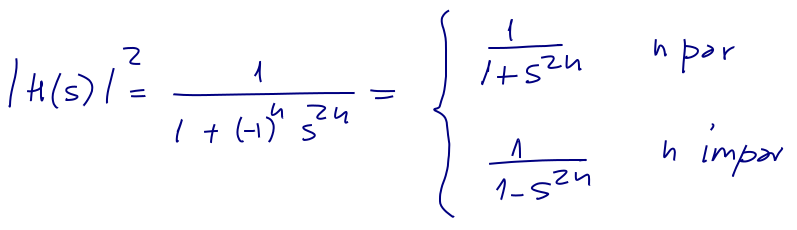

                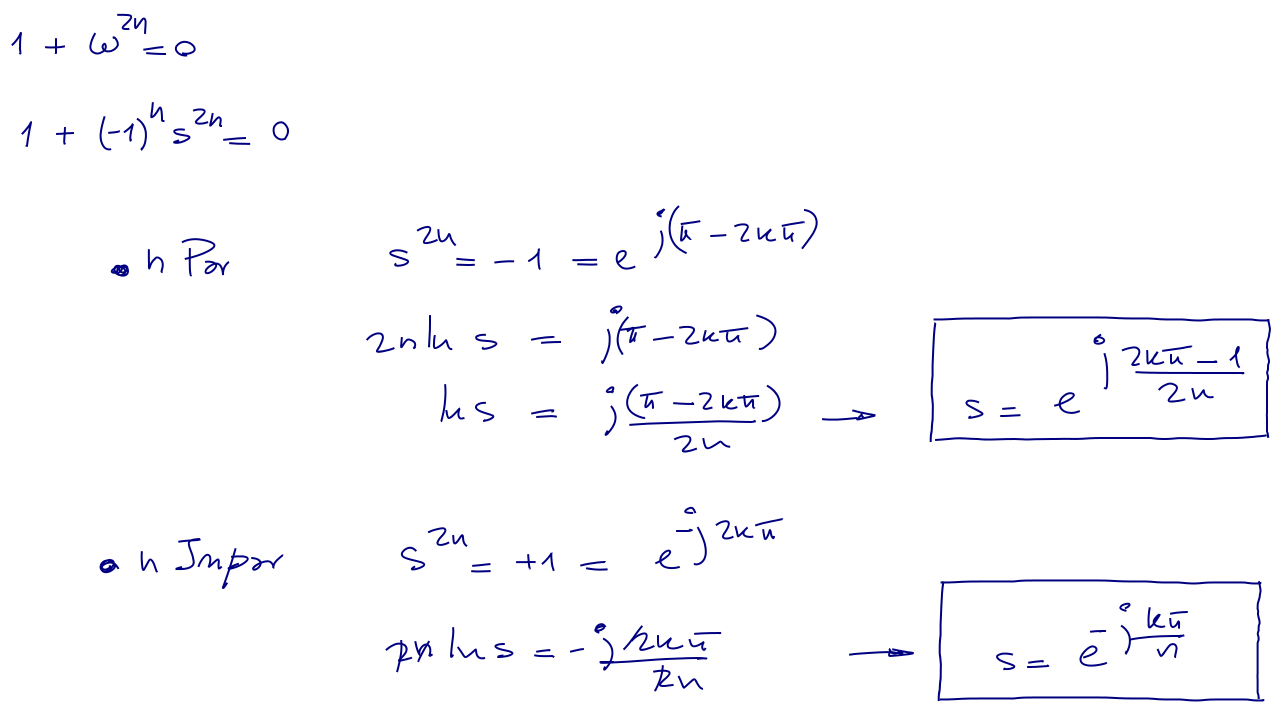


    syms s;
    syms k 'integer';

    theta(k) = -k*pi/N;
    if mod(N,2)==0
        theta(k) = ((2*k-1)/(2*N) )*pi;
    end    
    
    sk(k)=cos(theta(k)) + j*sin(theta(k));

    B=1;
    A=poly(LH(sk(0:2*N-1)));

end